defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 4 - In vivo');

%Examples for spatial analysis
filelist = loadFileList('.\Data\WT\*\*_dFoF_remflash*');

load(filelist{2})
[peakStat, eventStats] = spatialPeakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
h = plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat,[0 3000])

  0×1 empty cell array



h =   Figure (98) with properties:

      Number: 98
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 0 300 600]
       Units: 'pixels'

  Show all properties


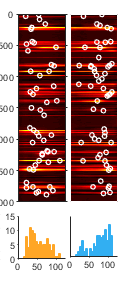

figQuality(gcf,gca,[1.25 3])
export_fig('.\EPS Panels\wt_spatial_analysis.eps')

%Examples for spatial analysis
filelist = loadFileList('.\Data\P2ry1 KO\*\*_dFoF_remflash.mat');

load(filelist{4})
[peakStat, eventStats] = spatialPeakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat,[0 3000])

  0×1 empty cell array



ans =   Figure (99) with properties:

      Number: 99
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 0 300 600]
       Units: 'pixels'

  Show all properties


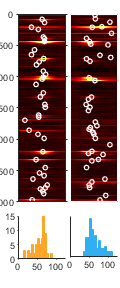

figQuality(gcf,gca,[1.25 3])
export_fig('.\EPS Panels\ko_spatial_analysis.eps')